SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 87.50%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%
SVM Accuracy (Autoencoder Features): 100.00%


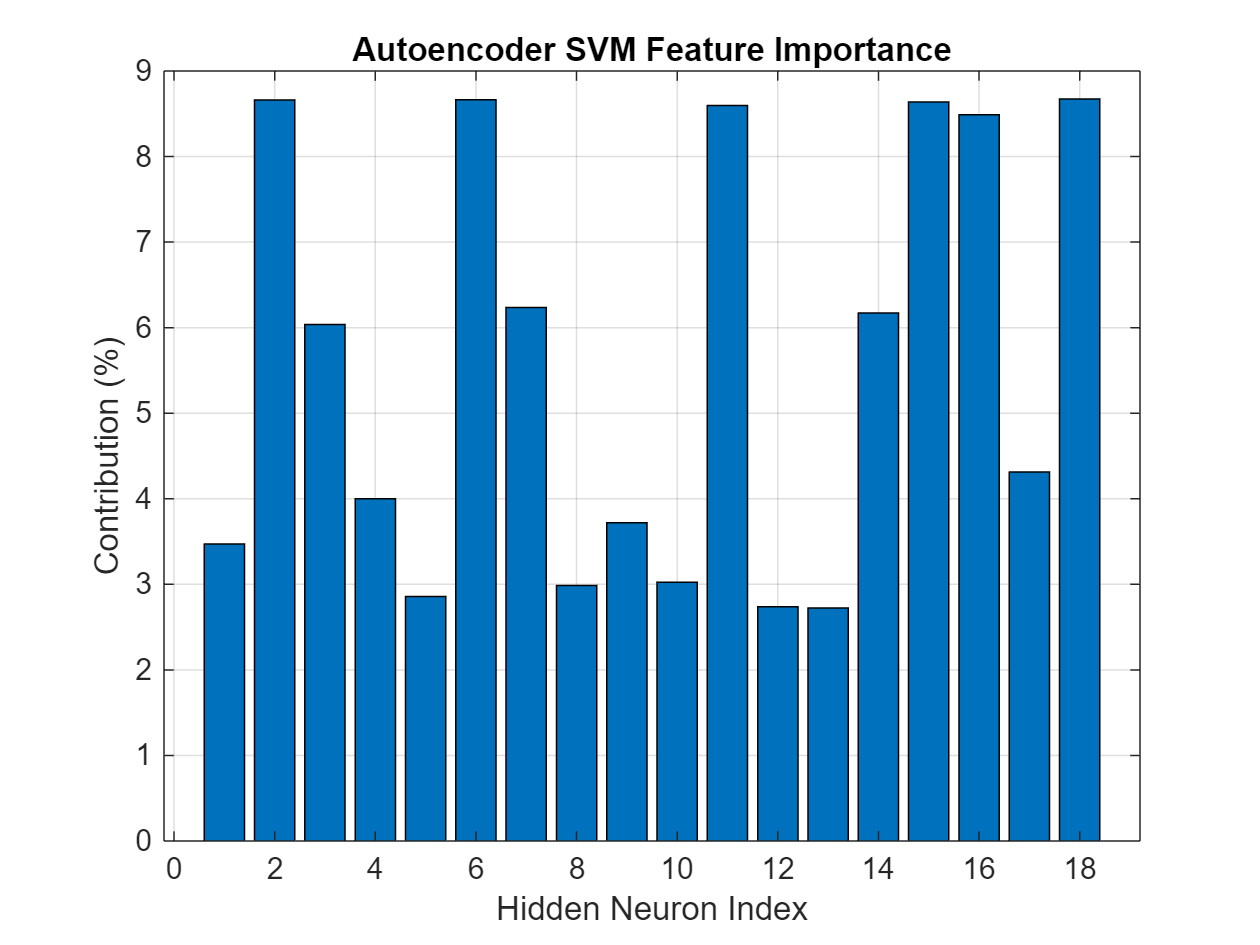

% %%%% Convert Selected Features to a Table  %%%%
% featureNamesAuto = [timeFreqFeatures.Properties.VariableNames, fftFeatures.Properties.VariableNames];
% featureTablenorm = array2table(allnormFeatures, 'VariableNames', featureNamesAuto);
% featureTablenorm.Label = labels; % Add Labels
% 
% %%%% View Selection  %%%%
% disp(featureTablenorm);
% 
% %%%% Convert Features to a Numeric Array  %%%%
% featureMatrixAuto = table2array(featureTablenorm(:, 1:end-1));
% 
% Xdata = featureMatrixAuto';
% auto = trainAutoencoder(Xdata,18,'MaxEpochs',5000,...
%     'EncoderTransferFunction','logsig',...
%     'DecoderTransferFunction','purelin',...
%     'L2WeightRegularization',0.004,...
%     'SparsityRegularization',4);
% 
% % Encode all features using the trained autoencoder
% normalEncodedFeatures = encode(auto, allnormFeatures');
% abnormalEncodedFeatures = encode(auto, abnfeatureMatrix');
% 
% % Combine normal and abnormal features
% combinedFeatures = [normalEncodedFeatures, abnormalEncodedFeatures];
% combinedFeatures = combinedFeatures';
% 
% % Create corresponding labels: 0 for normal, 1 for abnormal
% numNormal = size(normalEncodedFeatures, 2);
% numAbnormal = size(abnormalEncodedFeatures, 2);
% combinedLabels = [zeros(1, numNormal), ones(1, numAbnormal)];
% 
% % Convert features to table
% featureTableAutoencoder = array2table(combinedFeatures);
% 
% % Extract feature matrix and labels
% featureMatrixAutoencoder = table2array(featureTableAutoencoder);
% labelsAutoencoder = combinedLabels';
% 
% % Check for NaNs in the feature matrix
% if any(isnan(featureMatrixAutoencoder), 'all')
%     error('Feature matrix contains NaN values!');
% end

% Normalize features
featureMatrixAutoencoder = normalize(featureMatrixAutoencoder, 'zscore');

perfMod = 0.9; performanceMatrixdisplayAuto = zeros(9,1);

for perfModiter = 0.1:0.1:perfMod
    % Split Data
    cv = cvpartition(labelsAutoencoder, 'HoldOut', perfModiter);
    XTrainAuto = featureMatrixAutoencoder(training(cv), :);
    YTrainAuto = labelsAutoencoder(training(cv));
    XTestAuto = featureMatrixAutoencoder(test(cv), :);
    YTestAuto = labelsAutoencoder(test(cv));
    
    % Train SVM Model with linear kernel
    svmModelAuto = fitcsvm(XTrainAuto, YTrainAuto, 'KernelFunction', 'linear', 'Standardize', true);
    
    % Predict on Test Data
    YPredAuto = predict(svmModelAuto, XTestAuto);
    
    % Calculate Accuracy
    accuracyAuto = sum(YPredAuto == YTestAuto) / length(YTestAuto);
    fprintf('SVM Accuracy (Autoencoder Features): %.2f%%\n', accuracyAuto * 100);
        
    confusionchart(YTestAuto, YPredAuto);
    title('SVM Confusion Matrix (Autoencoder Features)');
    
    svmWeightsAuto = svmModelAuto.Beta;
    featureContributionAuto = abs(svmWeightsAuto) / sum(abs(svmWeightsAuto)) * 100;
    bar(featureContributionAuto);
    xlabel('Hidden Neuron Index');
    ylabel('Contribution (%)');
    title('Autoencoder SVM Feature Importance');
    grid on;
    
end